clear;clc;
%   we need two satellites and two base stations
%   The two satellites work as spatial diversity
%   redundant resources.
%   The one base station sends data to both satellites
%   This means it needs two gimbals
%   Then the both satellites send the data to the one
%   gimbal of the second base station.
%   Setting up the simulation scenario
clear;clc;
startTime = datetime(2020,1,11,14,00,0);
stopTime = startTime + days(1);
sampleTime = 60;

sc = satelliteScenario(...
    startTime,stopTime,sampleTime);

Launch satellite scenario viewer

% satelliteScenarioViewer(sc);

Add the satellites to the scenarios

%   using certain orbit propagator ! To-do: must check the orbit propagator
%   maths
sat1 = satellite(sc,earthRadius+600e3,0,60,0,0,0,"Name","Sat1","OrbitPropagator","two-body-keplerian");
sat2 = satellite(sc,earthRadius+600e3,0,50,0,0,0,"Name","Sat2","OrbitPropagator","two-body-keplerian");

Add the gimbals on the sats

%   Gimbals of satellite 1
g1Sat1 = gimbal(sat1,"MountingLocation",[0;1;2]);% meters
g2Sat1 = gimbal(sat1,"MountingLocation",[0;-1;2]);
%   Gimbals of satellite 2
g1Sat2 = gimbal(sat2,"MountingLocation",[0;1;2]);
g2Sat2 = gimbal(sat2,"MountingLocation",[0;-1;2]);

Add the receivers and transmitters on each gimbal

- Gimbal 1 on each satellite is the transmitter

- Gimbal 2 on each satellite is the receiver

We choose to have the same frequency on both satellites

%   Transmitters
%   Downlink Frequency at 20 GHz
sat1Tx = transmitter(g1Sat1,"MountingLocation",[0;0;1],Frequency=20e9,Power=15);
sat2Tx = transmitter(g1Sat2,"MountingLocation",[0;0;1],Frequency=20e9,Power=15);
gaussianAntenna(sat1Tx,"DishDiameter",0.5);
gaussianAntenna(sat2Tx,"DishDiameter",0.5);

%   Receivers
sat1Rx = receiver(g2Sat1,"MountingLocation",[0;0;1],GainToNoiseTemperatureRatio=3,RequiredEbNo=4);
sat2Rx = receiver(g2Sat2,"MountingLocation",[0;0;1],GainToNoiseTemperatureRatio=3,RequiredEbNo=4);
gaussianAntenna(sat1Rx,"DishDiameter",0.5);
gaussianAntenna(sat2Rx,"DishDiameter",0.5);

Adding the ground stations

name = "Lamia Base Station";
lat=38.875941904578895;
lon=22.437526584061686;
gs1 = groundStation(sc,...
    Name=name,Latitude=lat,Longitude=lon);

latitude = 52.2294963;                                              % degrees
longitude = 0.1487094;                                              % degrees
gs2 = groundStation(sc,latitude,longitude,Name="Ground Station 2");

Add two gimbals on each ground station

%   GS1 is the transmitter
g1Gs1 = gimbal(gs1,"MountingAngles",[0;180;0],"MountingLocation",[0;1;-5]);
g2Gs1 = gimbal(gs1,"MountingAngles",[0;180;0],"MountingLocation",[0;-1;-5]);
%   Adding the transmitters one meter above the gimbal
gs1Tx1 = transmitter(g1Gs1,"Name","GS1Tx1","MountingLocation",[0;0;1],...
    "Frequency",30e9,"Power",40,"BitRate",20);
gs1Tx2 = transmitter(g2Gs1,"Name","GS1Tx2","MountingLocation",[0;0;1],...
    "Frequency",30e9,"Power",40,"BitRate",20);
gaussianAntenna(gs1Tx1,"DishDiameter",2);
gaussianAntenna(gs1Tx2,"DishDiameter",2);

%   GS2 is the receiver
g1Gs2 = gimbal(gs2,"MountingAngles",[0;180;0],"MountingLocation",[0;1;-5]);
g2Gs2 = gimbal(gs2,"MountingAngles",[0;180;0],"MountingLocation",[0;-1;-5]);
%   Adding the receivers
gs2Rx1 = receiver(g1Gs2,"Name","GS2Rx1","MountingLocation",[0;0;1],...
    "GainToNoiseTemperatureRatio",3,"RequiredEbNo",1);
gs2Rx2 = receiver(g2Gs2,"Name","GS2Rx1","MountingLocation",[0;0;1],...
    "GainToNoiseTemperatureRatio",3,"RequiredEbNo",1);
gaussianAntenna(gs2Rx1,"DishDiameter",2);
gaussianAntenna(gs2Rx1,"DishDiameter",2);

Set the tracking of the targets for Gimbals

- Each gimbal must track the corresponding Satellite

The connections are:

- GS1Tx1 points at Sat1Rx

- GS1Tx2 points at Sat2Rx

- Sat1Tx points at GS2Rx1

- Sat2Tx points at GS2Rx2

pointAt(g1Gs1,sat1);
pointAt(g2Gs1,sat2);
pointAt(g2Sat1,gs1);
pointAt(g2Sat2,gs1);

pointAt(g1Gs2,sat1);
pointAt(g2Gs2,sat2);
pointAt(g1Sat1,gs2);
pointAt(g1Sat2,gs2);

Add Link Analysis and visualize scenario

acc1 = access(gs1,sat1);
acc2 = access(gs1,sat2);
acc3 = access(gs2,sat1);
acc4 = access(gs2,sat2);
accint1 = accessIntervals(acc1)

accint1 = 8×8 table
           Source           Target    IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ____________________    ______    ______________    ____________________    ____________________    ________    __________    ________

    "Lamia Base Station"    "Sat1"          1           11-Jan-2020 15:42:00    11-Jan-2020 15:52:00      600           2            2    
    "Lamia Base Station"    "Sat1"          2           11-Jan-2020 17:20:00    11-Jan-2020 17:33:00      780           3            3    
    "Lamia Base Station"    "Sat1"          3           11-Jan-2020 19:02:00    11-Jan-2020 19:12:00      600           4            4    
    "Lamia B

accint2 = accessIntervals(acc2)

accint2 = 7×8 table
           Source           Target    IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ____________________    ______    ______________    ____________________    ____________________    ________    __________    ________

    "Lamia Base Station"    "Sat2"          1           11-Jan-2020 15:42:00    11-Jan-2020 15:50:00      480           2            2    
    "Lamia Base Station"    "Sat2"          2           11-Jan-2020 17:20:00    11-Jan-2020 17:33:00      780           3            3    
    "Lamia Base Station"    "Sat2"          3           11-Jan-2020 19:01:00    11-Jan-2020 19:13:00      720           4            4    
    "Lamia B

accint3 = accessIntervals(acc3)

accint3 = 7×8 table
          Source          Target    IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    __________________    ______    ______________    ____________________    ____________________    ________    __________    ________

    "Ground Station 2"    "Sat1"          1           11-Jan-2020 17:23:00    11-Jan-2020 17:31:00      480           3            3    
    "Ground Station 2"    "Sat1"          2           11-Jan-2020 19:00:00    11-Jan-2020 19:12:00      720           4            4    
    "Ground Station 2"    "Sat1"          3           11-Jan-2020 20:40:00    11-Jan-2020 20:52:00      720           5            5    
    "Ground Station 2"

accint4 = accessIntervals(acc4)

accint4 = 6×8 table
          Source          Target    IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    __________________    ______    ______________    ____________________    ____________________    ________    __________    ________

    "Ground Station 2"    "Sat2"          1           11-Jan-2020 19:01:00    11-Jan-2020 19:11:00      600           4            4    
    "Ground Station 2"    "Sat2"          2           11-Jan-2020 20:40:00    11-Jan-2020 20:52:00      720           5            5    
    "Ground Station 2"    "Sat2"          3           11-Jan-2020 22:20:00    11-Jan-2020 22:33:00      780           6            6    
    "Ground Station 2"


lnk1 = link(gs1Tx1,sat1Rx,sat1Tx,gs2Rx1);
lnk2 = link(gs1Tx2,sat2Rx,sat2Tx,gs2Rx2);
lnk3 = link(gs1Tx1,sat2Rx,sat2Tx,gs2Rx1);
lnk4 = link(gs1Tx2,sat1Rx,sat1Tx,gs2Rx2);
lint1 = linkIntervals(lnk1)

lint1 = 7×8 table
     Source      Target     IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    ________    ______________    ____________________    ____________________    ________    __________    ________

    "GS1Tx1"    "GS2Rx1"          1           11-Jan-2020 17:23:00    11-Jan-2020 17:31:00      480          NaN          NaN   
    "GS1Tx1"    "GS2Rx1"          2           11-Jan-2020 19:02:00    11-Jan-2020 19:12:00      600          NaN          NaN   
    "GS1Tx1"    "GS2Rx1"          3           11-Jan-2020 20:46:00    11-Jan-2020 20:52:00      360          NaN          NaN   
    "GS1Tx1"    "GS2Rx1"          4           11-Jan-2020 22:28:

lint2 = linkIntervals(lnk2)

lint2 = 5×8 table
     Source      Target     IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    ________    ______________    ____________________    ____________________    ________    __________    ________

    "GS1Tx2"    "GS2Rx1"          1           11-Jan-2020 19:01:00    11-Jan-2020 19:11:00      600          NaN          NaN   
    "GS1Tx2"    "GS2Rx1"          2           11-Jan-2020 20:44:00    11-Jan-2020 20:52:00      480          NaN          NaN   
    "GS1Tx2"    "GS2Rx1"          3           11-Jan-2020 22:25:00    11-Jan-2020 22:33:00      480          NaN          NaN   
    "GS1Tx2"    "GS2Rx1"          4           12-Jan-2020 00:06:

lint3 = linkIntervals(lnk3)


lint3 =

  0×8 empty table

    Source    Target    IntervalNumber    StartTime    EndTime    Duration    StartOrbit    EndOrbit
    ______    ______    ______________    _________    _______    ________    __________    ________




lint4 = linkIntervals(lnk4)


lint4 =

  0×8 empty table

    Source    Target    IntervalNumber    StartTime    EndTime    Duration    StartOrbit    EndOrbit
    ______    ______    ______________    _________    _______    ________    __________    ________




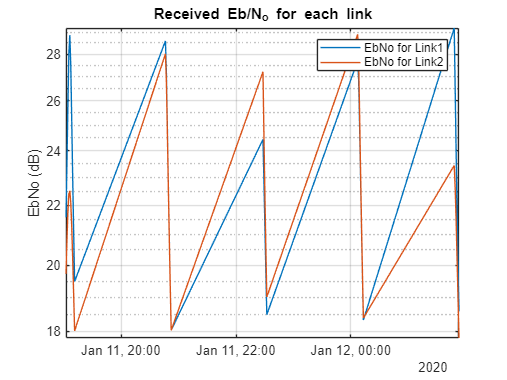


[e1,time1] = ebno(lnk1);
% plot(time1,e1);
[e2,time2] = ebno(lnk2);
% hold on;
% plot(time2,e2);
% hold off;
%   Plot when both links are closed
t = intersect(time1,time2);
t = t(e1 ~= -Inf & e2 ~= -Inf);
e1_new = e1(intersect(time1,time2) == time1 & e1 ~= -Inf & e2 ~= -Inf);
e2_new = e2(intersect(time1,time2) == time2 & e1 ~= -Inf & e2 ~= -Inf);
semilogy(t,e1_new);
hold on;
semilogy(t,e2_new);
hold off;
grid on;
axis tight;
ylabel('EbNo (dB)')
legend('EbNo for Link1', 'EbNo for Link2');
title('Received Eb/N_o for each link');

Bit Error Rate Analysis (BPSK)

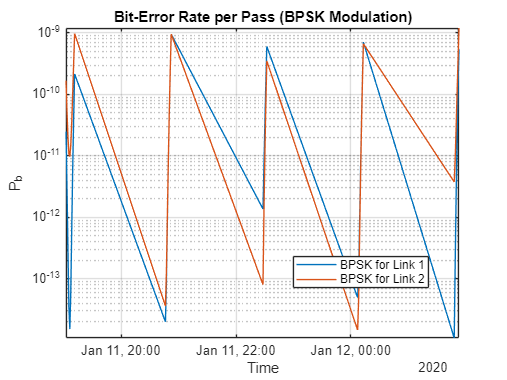

%   BPSK Error Rate
figure;
ber_bpsk1 = qfunc(sqrt(2*e1_new));
ber_bpsk2 = qfunc(sqrt(2*e2_new));
semilogy(t,ber_bpsk1);
hold on;
semilogy(t,ber_bpsk2);
hold off;
legend('BPSK for Link 1','BPSK for Link 2', 'Location','Best');
grid on;
axis tight;
ylabel('P_b');
xlabel('Time');
title('Bit-Error Rate per Pass (BPSK Modulation)');

Bit Error Rate Analysis (QPSK)

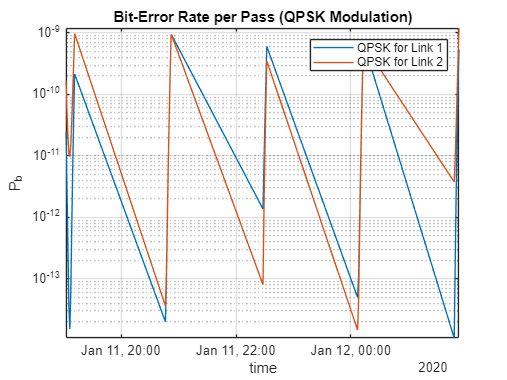


figure;
ber_qpsk1 = 0.5*(2*qfunc(sqrt(2*e1_new)) - (qfunc(sqrt(2*e1_new))).^2);
ber_qpsk2 = 0.5*(2*qfunc(sqrt(2*e2_new)) - (qfunc(sqrt(2*e2_new))).^2);
semilogy(t,ber_qpsk1);
hold on;
semilogy(t,ber_qpsk2);
hold off;
legend('QPSK for Link 1','QPSK for Link 2');
grid on;
axis tight;
ylabel('P_b');
xlabel('time');
title('Bit-Error Rate per Pass (QPSK Modulation)')

Combine the Eb/N0 from both links

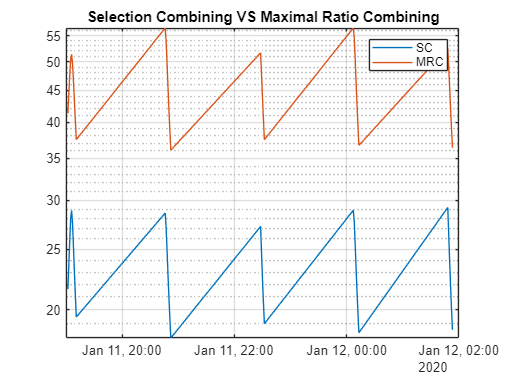

e = max(e1_new,e2_new);
e_2 = e1_new + e2_new;
figure;
semilogy(t,e,t,e_2);
grid on;
legend('SC','MRC');
title('Selection Combining VS Maximal Ratio Combining');

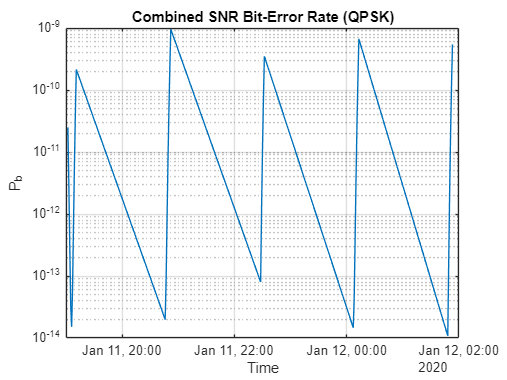

figure;
ber_qpsk = 0.5*(2*qfunc(sqrt(2*e)) - (qfunc(sqrt(2*e))).^2);
semilogy(t,ber_qpsk);
ylabel('P_b');
xlabel('Time');
title('Combined SNR Bit-Error Rate (QPSK)');
grid on;

Play the scenario

% play(sc);

Latency

% Step 1: Calculate latency and time
[delay, time] = latency(sat1,gs1); % Assuming lnk is your satellite link
[latency2,time2] = latency(sat1,gs2);

% Step 2: Get access intervals
ac = access(gs1, sat1);
intv = accessIntervals(ac);
ac2 = access(gs2,sat1);
intv2 = accessIntervals(ac2);

% Step 3: Plot latency per pass
figure;
hold on;
avg_pass_duration = 0;
number_of_passes = 0;
avg_latency = 0;
r = makedist('Rician','s',8,'sigma',5);
h11 = random(r,1,1);
h12 = random(r,1,1);
h21 = random(r,1,1);
h22 = random(r,1,1);
for i = 1:height(intv)
    % Extract start and end time of the i-th pass
    startTime = intv.StartTime(i);
    endTime = intv.EndTime(i);
    avg_pass_duration = avg_pass_duration + (endTime - startTime);
    number_of_passes = number_of_passes + 1;
    % Find indices within this pass
    idx = (time >= startTime) & (time <= endTime);
    avg_latency = avg_latency + sum(delay(idx));
    e1(idx & e2 ~= -Inf);
    e2(idx & e1 ~= -Inf);
    h11 = random(r,length(e1),1);
    h12 = random(r,length(e1),1);
    h1 = h11.*h12;
    h21 = random(r,length(e2),1);
    h22 = random(r,length(e2),1);
    h2 = h21.*h22;
    normh1 = sqrt(sum(h1.^2));
    normh2 = sqrt(sum(h2.^2));
    w1 = (1/normh1)*h1;
    w2 = (1/normh2)*h2;
    
    e = e1 + e2;
    % Plot latency for this pass
    % subplot(1,2,1);
    % plot(time(idx), delay(idx), 'LineWidth', 2, 'DisplayName', sprintf('Pass %d', i));
    % subplot(1,2,2);
    plot(time(idx),e(idx),'LineWidth',2,'DisplayName',sprintf('Pass %d', i));
end

for i = 1:height(intv2)
    startTime = intv2.StartTime(i);
    endTime = intv2.EndTime(i);
    idx = (time >= startTime) & (time <= endTime);
    avg_latency = avg_latency + sum(latency2(idx));
end

avpd = avg_pass_duration/number_of_passes

avpd = duration
   00:09:07


avl = avg_latency/number_of_passes

avl = 0.1323

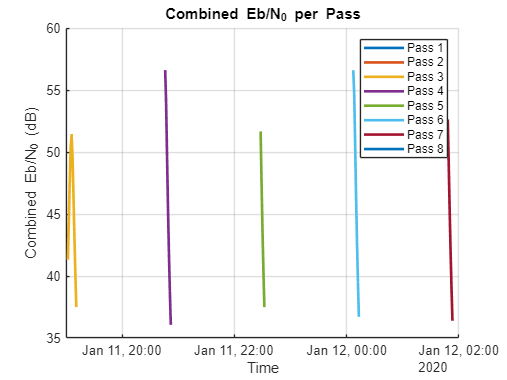

% Final plot formatting
xlabel('Time');
ylabel('Combined Eb/N_0 (dB)');
title('Combined Eb/N_0 per Pass');
grid on;
legend('show');
hold off;

Channels etc.

%   ebN0